Ejercicios de optimización de funciones

Encontrar un máximo o un mínimo local

7.3 Locate the minimum of the function 

f (x) = 3 + 6x + 5x^2 + 3x^3 + 4x^4 

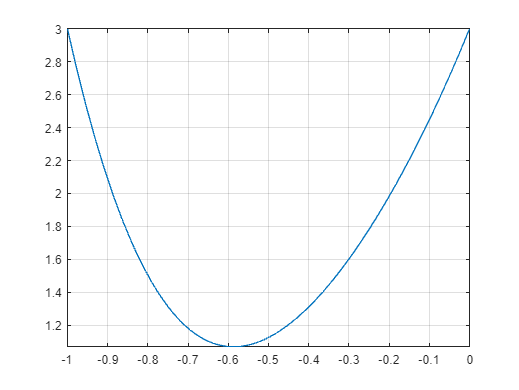

f = @(x) 3+6*x+5*x.^2+3*x.^3+4*x.^4;

fplot(f, [-1 0])
grid on


[x1(1),i1(1)] = O1_proporcionAurea(f,-1,0);
[x1(2),i1(2),min] = O2_newtonRaphsonMinimo(f,0)

x1 =    -0.5867   -0.5867


i1 =     38     5


min = logical
   1


7.2 Determine the maximum and the corresponding value of x for the function 

f (x) = −x^2 + 8x − 12

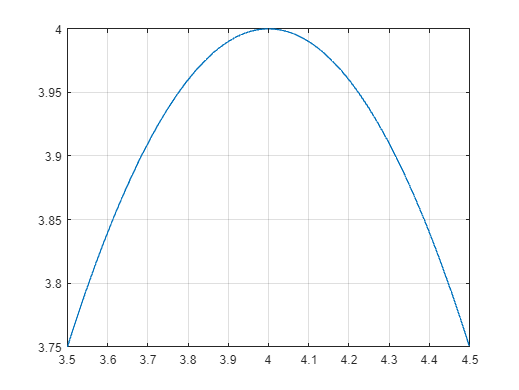

f = @(x) (-x.^2 +8*x -12);

fplot(f, [3.5 4.5])
grid on


g = @(x) -f(x);
%Máximos
[x2(1),i2(1)] = O1_proporcionAurea(g,3,5);
[x2(2),i2(2),min] = O2_newtonRaphsonMinimo(f,4.5)

x2 =     4.0000    4.0000


i2 =     35     2


min = logical
   0


7.4 Given 

f (x) = −1.5x^6 − 2x^4 + 12x 

(a) Plot the function. 

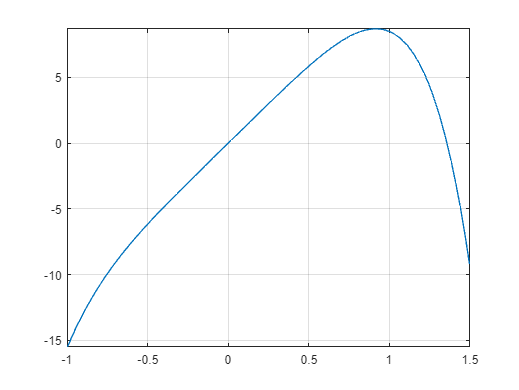

f = @(x) -1.5*x.^6-2*x.^4+12*x;

fplot(f,[-1 1.5])
grid on

(b) Use analytical methods to prove that the function is con­cave for all values of x. 

Si derivamos 2 veces, obtenemos que f''(x)=-45*x^4-24*x^2 la cuál siempre será negativa para toda x y por tanto f(x) es cóncava en todo su dominio. 

(c) Find the maximum f(x) and the corre­sponding value of x. 

g = @(x) -f(x);
%Máximos
[x3(1),i3(1)] = O1_proporcionAurea(g,.5,1.5);
[x3(2),i3(2)] = O2_newtonRaphsonMinimo(f,1)

x3 =     0.9169    0.9169


i3 =     37     5


Problema altura máxima

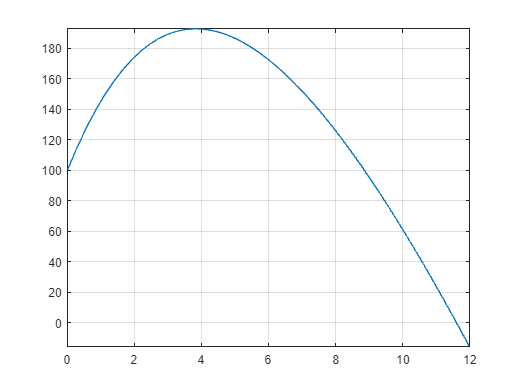

g = 9.81;
z0 = 100;
v0 = 55;
m = 80;
c = 15;

z = @(t) z0 + m/c*(v0 + m*g/c)*(1-exp(-c.*t/m))-m*g.*t/c;

fplot(z,[0 12])
grid on


[x4(1),i4(1),min] = O2_newtonRaphsonMinimo(z,1);
g = @(x) -z(x);
[x4(2),i4(2)] = O1_proporcionAurea(g,3,5)

x4 =     3.8317    3.8317


i4 =      5    35



AltMax = z(x4(1))

AltMax = 192.8609